clc; clear; close all;

# 1D-FC with Barycentric Interpolation Error Analysis

% function
% phi = @(y) exp(sin(2.7 * pi * y) + cos(pi*y));
phi = @(y) y.^3

phi = function_handle with value:
    @(y)y.^3



k_lst = [0.01, 0.005, 0.0025, 0.00125];
d_lst = 4:10;

err = zeros(length(d_lst), length(k_lst));

for i = 1:length(d_lst)
    d = d_lst(i);
    for j = 1:length(k_lst)
        % k and d, variable parameters
        k = k_lst(j);
        
        % error mesh
        k_err = k*0.05;
        D_err = transpose(0:k_err:1);
        phi_err = phi(D_err);
        
        % continuation points
        C = 27;
        
        %% 1D-FC
        % x mesh
        D = transpose(0:k:1);
        N = length(D);
        
        % left and right side of domain
        D_l = D(1:d);
        D_r = D(end-d+1:end);
        
        % shifted left side for computation
        D_l_C = D_l + (N+C-1)*k;
        
        % value of function on left and right side
        phi_l = phi(D_l);
        phi_r = phi(D_r);
        
        % grid values of interpolation
        D_interpolant = [D_r; D_l_C];
        phi_interpolant = [phi_r; phi_l];
        
        % interpolant weights and function
        w = barycentric_weights(D_interpolant);
        barycentric_func = barycentric_compute_func(w, phi_interpolant, D_interpolant);
        
        % continuation domain and vector
        D_C = transpose(D_r(end)+k:k:D_r(end)+(C-1)*k);
        phi_C = barycentric_func(D_C);
        
        % continuation function
        D_NC = [D; D_C];
        phi_NC = [phi(D); phi_C];
        
        %% FFT
        C_n = FFT_coeff(phi_NC);
        FS_func = FFT_compute_func(C_n);
        FS_scaled_func = @(x) FS_func((x-D_NC(1))./(D_NC(end)-D_NC(1)));
        
        err(i, j) = max(abs(FS_scaled_func(D_err) - phi_err));
    end
end

% % error mesh
% k_err = 0.0025*0.05;
% D_err = transpose(0:k_err:1);
% phi_err = phi(D_err);
% 
% % k and d, variable parameters
% k = 0.0025;
% d = 12;
% 
% % continuation points
% C = 27;
% 
% %% 1D-FC
% % x mesh
% D = transpose(0:k:1);
% N = length(D);
% 
% % left and right side of domain
% D_l = D(1:d);
% D_r = D(end-d+1:end);
% 
% % shifted left side for computation
% D_l_C = D_l + (N+C-1)*k;
% 
% % value of function on left and right side
% phi_l = phi(D_l);
% phi_r = phi(D_r);
% 
% % grid values of interpolation
% D_interpolant = [D_r; D_l_C];
% phi_interpolant = [phi_r; phi_l];
% 
% % interpolant weights and function
% w = barycentric_weights(D_interpolant);
% barycentric_func = barycentric_compute_func(w, phi_interpolant, D_interpolant);
% 
% % continuation domain and vector
% D_C = transpose(D_r(end)+k:k:D_r(end)+(C-1)*k);
% phi_C = barycentric_func(D_C);
% 
% % continuation function
% D_NC = [D; D_C];
% phi_NC = [phi(D); phi_C];
% 
% %% FFT
% C_n = FFT_coeff(phi_NC);
% FS_func = FFT_compute_func(C_n);
% FS_scaled_func = @(x) FS_func((x-D_NC(1))./(D_NC(end)-D_NC(1)));
% 
% max(abs(FS_scaled_func(D_err) - phi_err))
% FS_scaled_func(D_err)
% phi_err
% 
% figure;
% hold on;
% plot(D_err, FS_scaled_func(D_err))
% plot(D_err, phi(D_err))

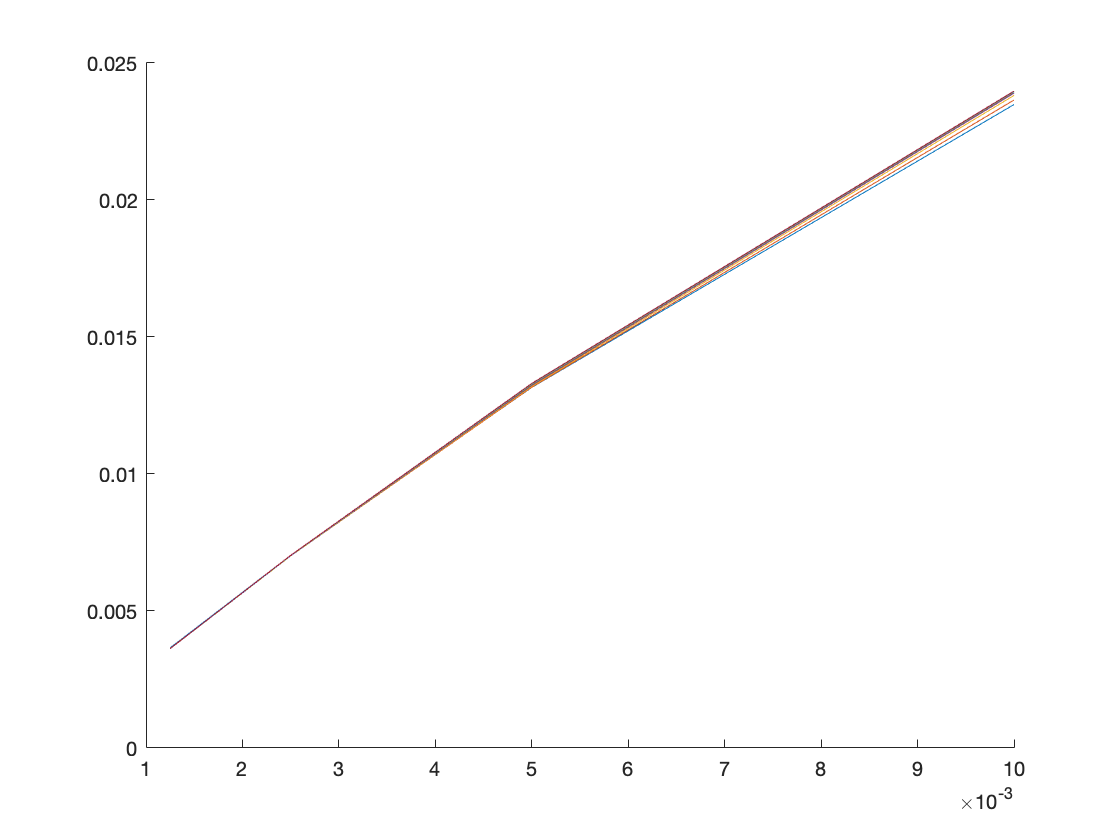

figure;
hold on;
loglog(k_lst, err)